clear all
close all
clc

%Log data
AT_R = [7/43,12/43,20/43,33/43,38/43];
HT_R = 1 - AT_R;

AT_S = [5/41,9/41,21/41,34/41,38/41];
HT_S = 1 - AT_S;

WaitingTime = [10,7,5,3,1];

ColorCode = ["#0072BD",	"#4DBEEE",	"#D95319",	"#EDB120"]

ColorCode = 1×4 string array
    "#0072BD"    "#4DBEEE"    "#D95319"    "#EDB120"


legend_Price = ["AT-Rainy","HT-Rainy","AT-Sunny","HT-Sunny"]

legend_Price = 1×4 string array
    "AT-Rainy"    "HT-Rainy"    "AT-Sunny"    "HT-Sunny"



WTPlot=[AT_R;HT_R;AT_S;HT_S];

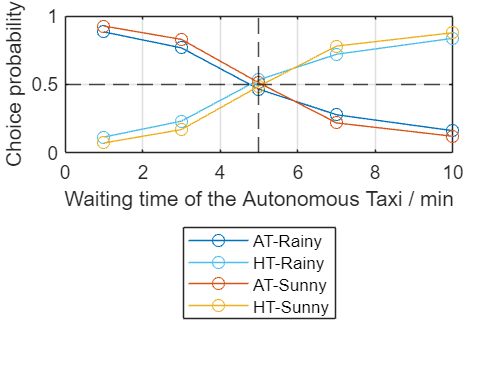

%Plot
for i = 1:4
    plot(WaitingTime,WTPlot(i,:),'o-','DisplayName',legend_Price(i),color=ColorCode(i))
    hold on
end

xlabel('Waiting time of the Autonomous Taxi / min')
ylabel('Choice probability')
legend(Location="southoutside")

xline(5,'k--','HandleVisibility','off')
yline(0.5,'k--','HandleVisibility','off')
grid on
hold off

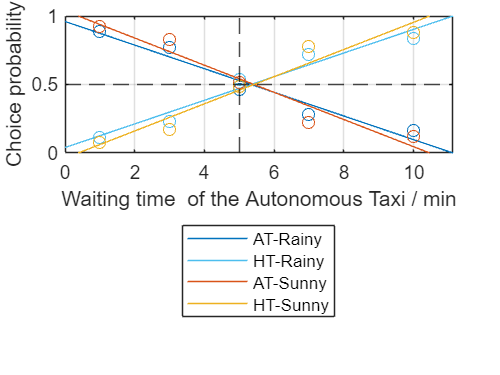

%Linear regression
dataRange = [0:0.01:12];
for j = 1:4
    fit = polyfit(WaitingTime,WTPlot(j,:),1);
    plot(dataRange,polyval(fit,dataRange),'DisplayName',legend_Price(j),color=ColorCode(j))
    hold on
    scatter(WaitingTime,WTPlot(j,:),'o','HandleVisibility','off','MarkerEdgeColor',ColorCode(j))
end

xlabel('Waiting time  of the Autonomous Taxi / min')
ylabel('Choice probability')
legend(Location="southoutside")

ylim([0 1])

xline(5,'k--','HandleVisibility','off')
yline(0.5,'k--','HandleVisibility','off')
grid on
hold off